# Test PenguinPi web API

url = "10.0.0.20";
robot = PiBot(url)

PenguinPi robot at http://10.0.0.20:8080


## Test ADC

robot.getVoltage()

ans = 7.7940

robot.getCurrent()

ans = 0.4031

## Test LEDs

for i=2:4
    robot.setLED(i, 1);
    pause(0.5)
    robot.setLED(i, 0);
end

for i=2:4
    robot.pulseLED(i, 0.1);
    pause(0.5)
end


## Test HAT

robot.getDIP()

ans = '5'

robot.getButton()

ans = '0'

for i=0:15
    robot.setLEDArray(2^i);
end
robot.setLEDArray(0);

for i=0:6
    robot.setLEDArray(i);
    pause(1)
end
robot.setLEDArray(0);

pause(0.5)
% left arrow
robot.setLEDArray( hex2dec('4e44'));
pause(1)
% right arrow
robot.setLEDArray( hex2dec('44e4'));
pause(1)
robot.setLEDArray(0);

robot.printfOLED("hello world\n")

## Robot

### Test move

stat1 = robot.setVelocity(20, -20)

stat1 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


pause(2)
stat2 = robot.stop()

stat2 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]



pause(2)

stat1 = robot.setVelocity([20, -20])

stat1 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


pause(2)
stat2 = robot.stop()

stat2 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


### Test move with time

stat1 = robot.setVelocity([20, -20], 2)

stat1 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


pause(2)

### Test move with time and acceleration

stat1 = robot.setVelocity([20, -20], 2, 0.5)

stat1 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


pause(2)

## Camera

img = robot.getImage();
about img

img [uint8] : 240x320x3 (230.4 kB)


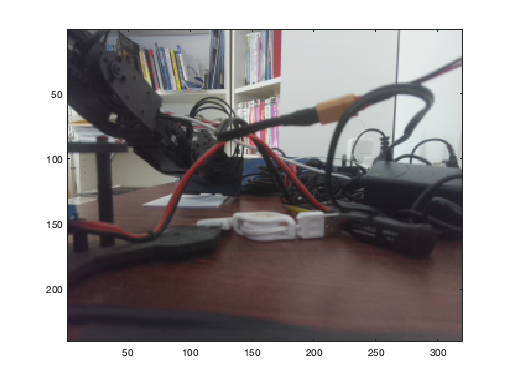

image(img)